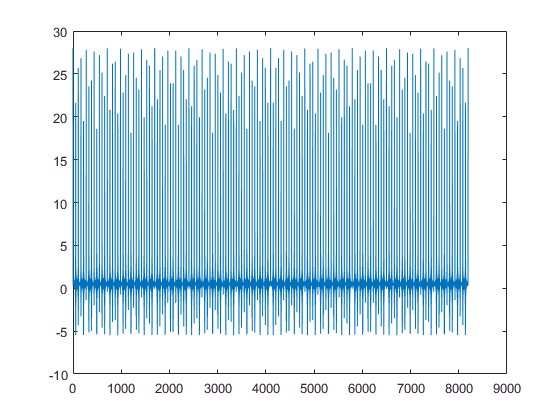

nsamples = 8192; % Duration of the glottal signal in samples
f0 = 150; % Pitch in Hz
fs=8192;
nharm = floor((fs/2)/f0); % Number of harmonics to generate band-limited impulse train

% Generate the glottal signal (source) here and visualize
%
glottalSignal = glottal(f0, fs, nharm, nsamples);
figure(1);
plot(glottalSignal);

%
% Normalize the glottal signal by dividing every sample by the maximum
% value. 

normGlottal = glottalSignal./(max(glottalSignal(:)));

## Vocal tract Filter model

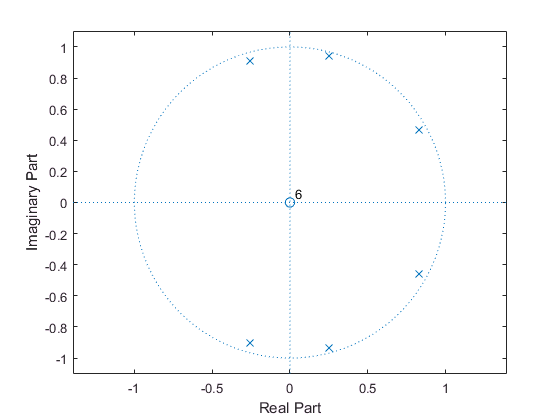

eVowel = [400 1700 2300];
aVowel = [609 100 2450];
bootVowel = [440 1000 2250];
batVowel = [660 1700 2400];
F =  batVowel; % Specify the formant frequencies for vowel /a/ (Hz) 
BW = [130,  70,  160];  % Formant bandwidths (Hz)

fs = 8192;              % Sampling rate (Hz)

R = exp(-pi*BW*(1/fs));     % Pole radii
theta = ((2*pi)/fs)*F;      % Pole angles
poles = R.*exp(i*theta); % Generate complex poles using R and theta. Don't forget the symmetry in the pole-zero plot! 
B = 1;  % Numerator coefficients of the transfer function of the filter
A = real(poly([poles,conj(poles)])); % Denominator coefficients of the transfer function

% Visualize frequency response and pole-zero plot of the vocal tract filter:
figure(2);
zplane(B, A);

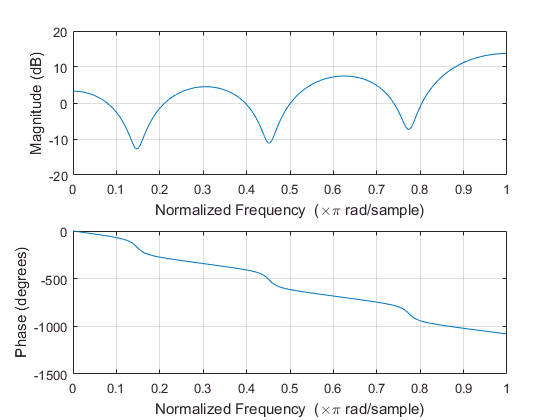

figure(3);
freqz(B./A);

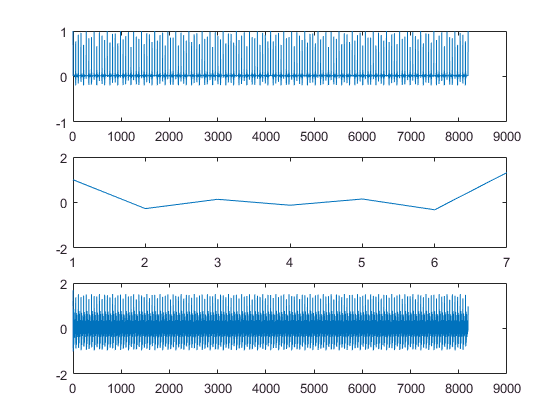


% Now synthesize the vowel and listen to it:
vowel = filter(B, A, normGlottal);
figure(4);
subplot(3, 1, 1); plot(normGlottal);
subplot(3, 1, 2); plot(vocalTractFilter);
subplot(3, 1, 3); plot(vowel);

soundsc(vowel);